% audusdDS = imageDatastore("AUDUSD","IncludeSubfolders",true, "LabelSource","foldernames", "ReadFcn", @customreader)
% outputs = audusdDS.Labels;
% [inputTrain,inputValidation, inputTest] = splitEachLabel(audusdDS, 0.7, 0.15)
clear;clc;close all

inputSize1=[1020 1632];
inputSize2=[1020 1632];

firstFolderName='AUDUSD1';
secondFolderName='AUDUSD2';
imdsMain = imageDatastore(strcat(firstFolderName,filesep), 'IncludeSubfolders',true, 'LabelSource','foldernames', "ReadFcn", @customreader);
imdsGaps = imageDatastore(strcat(secondFolderName,filesep), 'IncludeSubfolders',true, 'LabelSource','foldernames', "ReadFcn", @customreader);
augmenter = imageDataAugmenter('RandXReflection',false);
augimdsMain = augmentedImageDatastore(inputSize1,imdsMain,'DataAugmentation',augmenter);
augimdsGaps = augmentedImageDatastore(inputSize2,imdsGaps,'DataAugmentation',augmenter);
numAll=numel(imdsMain.Files);

% The ratio is specified here
TrainRatio=0.8;
ValidRatio=0.1;
TestRatio=1-TrainRatio-ValidRatio;

[XTrainMain,XTrainGaps,XValidMain,XValidGaps,XTestMain,XTestGaps,YTrain,YValid,YTest]=partitionData(augimdsMain,augimdsGaps,TrainRatio,ValidRatio,numAll,imdsMain.Labels);
classes = categories(YTrain); % retrieve the class names
numClasses = numel(classes); % the number of classes


numHiddenDimension=20; % speficy the dimension of the hidden layer
layers = createSimpleLayer(XTrainMain, numHiddenDimension);
layers2 = createSimpleLayer(XTrainGaps, numHiddenDimension);

When the two layers are merged, the same name of the layers cannot be used. Use renameLayer function to rename the layer name in `layers2`

layers2=renameLayer(layers2,'_2');
layersAdd=[fullyConnectedLayer(20,'Name','fcAdd1')
    fullyConnectedLayer(numClasses,'Name','fcAdd2')];
layersRemoved=[layers(1:end);concatenationLayer(1,2,'Name','cat');layersAdd];
lgraphAggregated = addLayers(layerGraph(layersRemoved),layers2(1:end));
lgraphAggregated = connectLayers(lgraphAggregated,'fc_2','cat/in2');

Covert into deep learning network for custom training loops using `dlnetwork`

dlnet = dlnetwork(lgraphAggregated); % A dlnetwork object enables support for custom training loops using automatic differentiation


## **Specify training options**

miniBatchSize = 16; % mini batch size. When you run out of memory, decrease this value like 4 
numEpochs = 30; % max epoch
numObservations = numel(YTrain); % the number of training data
numIterationsPerEpoch = floor(numObservations./miniBatchSize); % number of iterations per epoch
executionEnvironment = "gpu"; % Set "gpu" when you use gpu 

Initial setting for `Adam` optimizer

averageGrad = [];
averageSqGrad = [];
iteration = 1; % initialize iteration

## Create `animated line`

`animatedline` creates an animated line that has no data and adds it to the current axes. Create an animation by adding points to the line in a loop using the `addpoints` function.

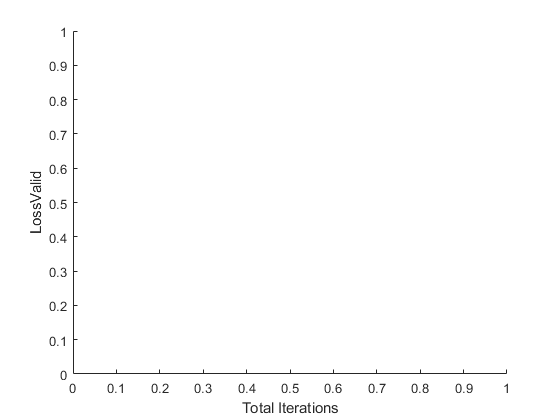

plots = "training-progress";
if plots == "training-progress"
    f1=figure;
    lineLossTrain = animatedline('Color','r');
    xlabel("Total Iterations")
    ylabel("Loss");lineLossValid = animatedline('Color','b');
    xlabel("Total Iterations");ylabel("LossValid")
end

## Prepare the validation data

The validation data is called during training to check the CNN performance. 

YValidPlot=zeros(numClasses,numel(YValid),'single');
for c = 1:numClasses
    YValidPlot(c,YValid==classes(c)) = 1;
end
% Convert mini-batch of data to a dlarray.
dlXValidMain=dlarray(single(XValidMain),'SSCB');
dlXValidGaps=dlarray(single(XValidGaps),'SSCB');

% If training on a GPU, then convert data to a gpuArray.
if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlXValidMain = gpuArray(dlXValidMain);
    dlXValidGaps = gpuArray(dlXValidGaps);
end

## Train network in custom training loop

for epoch = 1:numEpochs
    % Shuffle data.
    idx = randperm(numel(YTrain));
    XTrainMain = XTrainMain(:,:,:,idx);
    XTrainGaps = XTrainGaps(:,:,:,idx);
    YTrain=YTrain(idx);
    
    for i = 1:numIterationsPerEpoch
        
        % Read mini-batch of data and convert the labels to dummy
        % variables.
        idx = (i-1)*miniBatchSize+1:i*miniBatchSize;
        XMain = XTrainMain(:,:,:,idx);
        XGaps = XTrainGaps(:,:,:,idx);
        
        Y = zeros(numClasses, miniBatchSize, 'single');
        for c = 1:numClasses
            Y(c,YTrain(idx)==classes(c)) = 1;
        end
        
        % Convert mini-batch of data to a dlarray.
        dlXMain = dlarray(single(XMain),'SSCB');
        dlXGaps = dlarray(single(XGaps),'SSCB');
        
        % If training on a GPU, then convert data to a gpuArray.
        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            dlXMain = gpuArray(dlXMain);
            dlXGaps = gpuArray(dlXGaps);
        end
        
        % Evaluate the model gradients and loss using dlfeval and the
        % modelGradients helper function.
        [grad,loss] = dlfeval(@modelGradientsMulti,dlnet,dlXMain,dlXGaps,Y);
        lossValid = modelLossMulti(dlnet,dlXValidMain,dlXValidGaps,YValidPlot);
        % Update the network parameters using the Adam optimizer.
        [dlnet,averageGrad,averageSqGrad] = adamupdate(dlnet,grad,averageGrad,averageSqGrad,iteration,0.0005);
        
        % Display the training progress.
        if plots == "training-progress"
            addpoints(lineLossTrain,iteration,double(gather(extractdata(loss))))
            title("Loss During Training: Epoch - " + epoch + "; Iteration - " + i)
            addpoints(lineLossValid,iteration,double(gather(extractdata(lossValid))))
            title("Loss During Validation: Epoch - " + epoch + "; Iteration - " + i)
            drawnow
        end
        
        % Increment the iteration counter.
        iteration = iteration + 1;
    end
end

Error using nnet.internal.cnn.dlnetwork/forward (line 254)
Layer 'conv_1': Invalid input data. Out of memory on device. To view more detail about available memory on the GPU, use 'gpuDevice()'. If the problem persists, reset the GPU by calling 'gpuDevice(1)'.

Error in nnet.internal.cnn.dlnetwork/CodegenOptimizationStrategy/propagateWithFa

## Compute classification accuracy 

dlXTestMain = dlarray(single(XTestMain),'SSCB');
dlXTestGaps = dlarray(single(XTestGaps),'SSCB');

Convert the test data into `gpuArray` to accelarate with GPU

if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlXTestMain = gpuArray(dlXTestMain);
    dlXTestGaps = gpuArray(dlXTestGaps);
end

Two similar function are available in MATLAB for calculating the output of deep learning network. 

`predict`: Compute deep learning network output for inference

`forward`: Compute deep learning network output for training

The difference is either for training or testing. In the training phase, some techniques like batch normalization and dropout are employed while they are not used in testing.

dlYPred = predict(dlnet,dlXTestMain,dlXTestGaps); % use predict for testing
[~,idx] = max(extractdata(dlYPred),[],1); % extract the class with highest score
YPred = classes(idx);

Calculate the overall accuracy

accuracy = mean(YPred==YTest)

Display confusion matrix 

confusionchart(YTest,categorical(cellstr(YPred)))

function data = customreader(filename)
    data = imread(filename);
    data = imresize(data,[1020 1632]);
    %data = rgb2gray(data);
end

function data = customreadergray(filename)
    data = imread(filename);
    data = imresize(data,[1020 1632]);
    data = rgb2gray(data);
end

function [XTrainMain,XTrainGaps,XValidMain,XValidGaps,XTestMain,XTestGaps,YTrain,YValid,YTest]=partitionData(main,gaps,TrainRatio,ValidRatio,numAll,labels)
    %indices=randperm(numAll,numAll);
    indices=1:numAll;
    TrainIdx=indices(1:round(numel(indices)*TrainRatio));
    ValidIdx=indices(round(numel(indices)*TrainRatio)+1:round(numel(indices)*(TrainRatio+ValidRatio)));
    TestIdx=indices(round(numel(indices)*(TrainRatio+ValidRatio))+1:end);
    imdsTrainMain = partitionByIndex(main,TrainIdx);
    imdsTrainGaps = partitionByIndex(gaps,TrainIdx);
    imdsValidMain = partitionByIndex(main,ValidIdx);
    imdsValidGaps = partitionByIndex(gaps,ValidIdx);
    imdsTestMain = partitionByIndex(main,TestIdx);
    imdsTestGaps = partitionByIndex(gaps,TestIdx);
    XTrainMain=readall(imdsTrainMain);
    XTrainMain=cat(4,XTrainMain.input{:});
    XTrainGaps=readall(imdsTrainGaps);
    XTrainGaps=cat(4,XTrainGaps.input{:});
    XValidMain=readall(imdsValidMain);
    XValidMain=cat(4,XValidMain.input{:});
    XValidGaps=readall(imdsValidGaps);
    XValidGaps=cat(4,XValidGaps.input{:});
    XTestMain=readall(imdsTestMain);
    XTestMain=cat(4,XTestMain.input{:});
    XTestGaps=readall(imdsTestGaps);
    XTestGaps=cat(4,XTestGaps.input{:});
    YTrain=labels(TrainIdx);
    YValid=labels(ValidIdx);
    YTest=labels(TestIdx);
end

function layers=createSimpleLayer(XTrainData_4D, numHiddenDimension)
    layers = [
        imageInputLayer([1020 1632 3],"Name","imageinput","Mean",mean(XTrainData_4D,4))
        convolution2dLayer([3 3],8,"Name","conv_1","Padding","same")
        reluLayer("Name","relu_1")
        maxPooling2dLayer([2 2],"Name","maxpool_1","Stride",[2 2])
        convolution2dLayer([3 3],16,"Name","conv_2","Padding","same")
        reluLayer("Name","relu_2")
        maxPooling2dLayer([2 2],"Name","maxpool_2","Stride",[2 2])
        convolution2dLayer([3 3],32,"Name","conv_3","Padding","same")
        reluLayer("Name","relu_3")
        fullyConnectedLayer(numHiddenDimension,"Name","fc")];
end

function [gradients,loss] = modelGradientsMulti(dlnet,dlXMain,dlXGaps,Y)

    dlYPred = forward(dlnet,dlXMain,dlXGaps);
    dlYPred = softmax(dlYPred);
    
    loss = crossentropy(dlYPred,Y);
    gradients = dlgradient(loss,dlnet.Learnables);

end

function layers=renameLayer(layers,char)
   for i=1:numel(layers)
       layers(i).Name=[layers(i).Name,char];
   end
end

function loss = modelLossMulti(dlnet,dlXMain,dlXGaps,Y)
    dlYPred = forward(dlnet,dlXMain,dlXGaps);
    dlYPred = softmax(dlYPred);
    loss = crossentropy(dlYPred,Y);
end